# Example

The following table shows measurements of reaction temperature versus time. Determine the 1st – order, 2nd – order, 4th – order, and 8th-order polynomials to represent this data and reaction temperature when t = 4.26 hr.

## Solution

clear, clc
t = 1:8;        % time (hr)
T = [50.8 54.4 55.1 57.6 61.2 59.5 54.6 53.5];      % Temperature(K)

Coeff_1st = polyfit(t,T,1)

Coeff_1st =     0.4369   53.8714


Coeff_2nd = polyfit(t,T,2)

Coeff_2nd =    -0.5875    5.7244   45.0589


Coeff_4th = polyfit(t,T,4)

Coeff_4th =     0.0365   -0.7161    4.1840   -6.4515   54.2089


Coeff_8th = polyfit(t,T,8)

Coeff_8th =    -0.0009    0.0251   -0.2784    1.4817   -3.7533    3.5366         0    3.7842   46.0050


time = 4.26;
result_1 = polyval(Coeff_1st,time);
result_2 = polyval(Coeff_2nd,time);
result_4 = polyval(Coeff_4th,time);
result_8 = polyval(Coeff_8th,time);
disp(table(result_1,result_2,result_4,result_8))

    result_1    result_2    result_4    result_8
    ________    ________    ________    ________

     55.733      58.783      59.301      58.675 



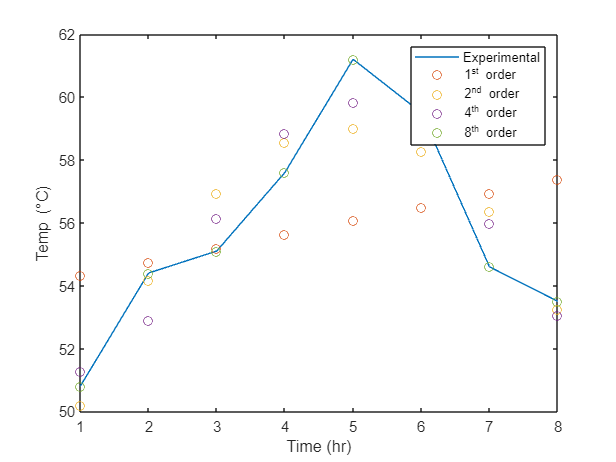

figure
plot(t,T)
hold on
plot(t,polyval(Coeff_1st,t),'o')
plot(t,polyval(Coeff_2nd,t),'o')
plot(t,polyval(Coeff_4th,t),'o')
plot(t,polyval(Coeff_8th,t),'o')
xlabel('Time (hr)')
ylabel('Temp (\circC)')
legend('Experimental', '1^{st} order', '2^{nd} order','4^{th} order','8^{th} order')